## PROBLEM 4.0

%{
ES 115 CLASS PROJECT PROBLEM 4.0
PROBLEM TITLE: Two Sensor Calibration and Agreement Check (Linear fit +
error)
DESCRIPTION: This program calibrates two linear sensor models using two 
             known points each. It then compares their outputs across a 
             range and identifies where they provide the most similar data.
PURPOSE:To perform linear curve fitting, error calculation, and 
         optimization (finding minimum absolute error).
INPUTS: 
    ~ Calibration points for Sensor 1: (x1, y1a) and (x2, y1b)
    ~ Calibration points for Sensor 2: (x3, y2a) and (x4, y2b)
    ~ x - Range of the measured quantity (0 to 30 units)
OUTPUTS:
    ~ m1, b1 / m2, b2 - Calibration coefficients for both sensors
    ~ y1, y2 - Calculated sensor outputs over the range
    ~ e(x) - The error (difference) between the two sensors
    ~ Best_x - The x-value where sensors agree best
ENGINNERING ALGORITHMS:
- Compute slope: m = (y_final - y_start) / (x_final - x_start)
- Compute intercept: b = y - m*x
- Evaluate linear models: y = mx + b
- Error analysis: e = y1 - y2
- Optimization: Find index of min(abs(e))

MATLAB TOOLS/FUNCTIONS:
- Basic Arithmetic & Array operations
- plot(), figure(), hold on
- min() and abs() functions
- find() or logical indexing
%}

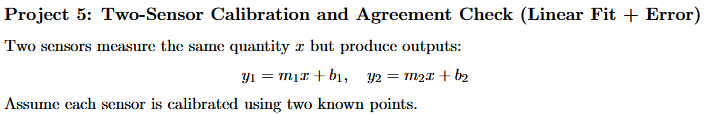

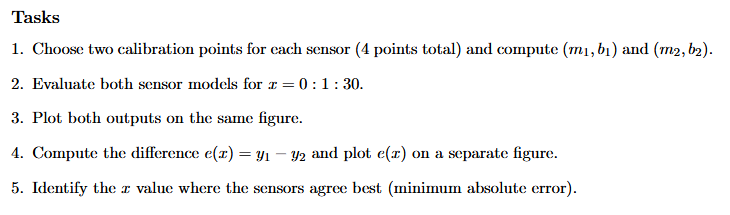

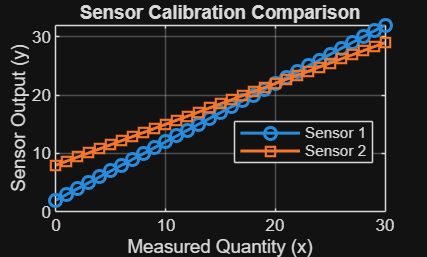

clc; clear; close all;

% Compute linear calibration slope from two calibration points
x1_cal = [0, 30]; y1_cal = [2, 32];
% Compute slope m1 = (y2-y1)/(x2-x1)
m1 = (y1_cal(2) - y1_cal(1)) / (x1_cal(2) - x1_cal(1));
% Compute intercept b1 for the line y = m1*x + b1
b1 = y1_cal(1) - m1 * x1_cal(1);

% Compute linear calibration slope and intercept from two reference points
x2_cal = [0, 30]; y2_cal = [8, 29];
% Compute slope and intercept of line through two calibration points
m2 = (y2_cal(2) - y2_cal(1)) / (x2_cal(2) - x2_cal(1));
b2 = y2_cal(1) - m2 * x2_cal(1);

% Precompute x and two linear functions for plotting or comparison
x = 0:1:30;
y1 = m1 .* x + b1;
y2 = m2 .* x + b2;

figure(1);
% Plot sensor 1 against x with markers and thicker line for visibility
plot(x, y1, '-o', 'LineWidth', 1.5); hold on;
% Plot sensor 2 with different marker for comparison
plot(x, y2, '-s', 'LineWidth', 1.5);
grid on;
title('Sensor Calibration Comparison');
xlabel('Measured Quantity (x)');
ylabel('Sensor Output (y)');
legend('Sensor 1', 'Sensor 2', 'Location', 'best');

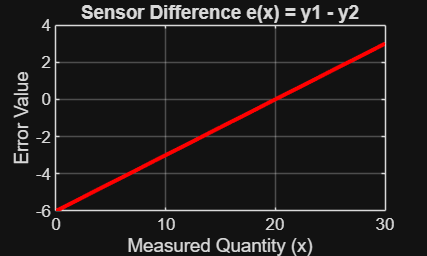


err = y1 - y2;

% Create or select figure window 2 for plotting
figure(2);
% Plot error vs x in red, thicker line for visibility
plot(x, err, 'r', 'LineWidth', 2);
% Enable grid to aid visual reading of values
grid on;
% Title explains plotted quantity is difference between two sensors
title('Sensor Difference e(x) = y1 - y2');
xlabel('Measured Quantity (x)');
ylabel('Error Value');



% Pick the x value corresponding to the smallest absolute error
[min_val, idx] = min(abs(err));
best_x = x(idx);

% Print fitted line for sensor 1
fprintf('Sensor 1 Model: y = %.2fx + %.2f\n', m1, b1);

Sensor 1 Model: y = 1.00x + 2.00


% Print fitted line for sensor 2
fprintf('Sensor 2 Model: y = %.2fx + %.2f\n', m2, b2);

Sensor 2 Model: y = 0.70x + 8.00


% Report x where sensors agree best and the corresponding absolute error
fprintf('Sensors agree best at x = %d (Absolute Error = %.4f)\n', best_x, min_val);

Sensors agree best at x = 20 (Absolute Error = 0.0000)
